## Example 1: Load and Display Image

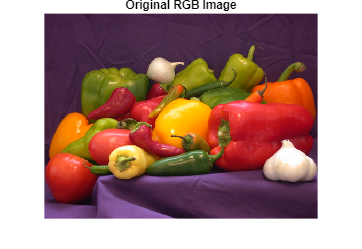

img = imread('peppers.png'); 
figure; imshow(img); title('Original RGB Image');

disp(size(img));

   384   512     3



## Example 2: Resize the Image

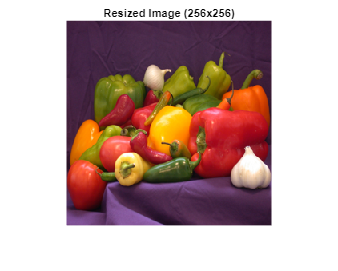

resizedImg = imresize(img, [256 256]);
figure; imshow(resizedImg); title('Resized Image (256x256)');

## Example 3: Convert to Grayscale

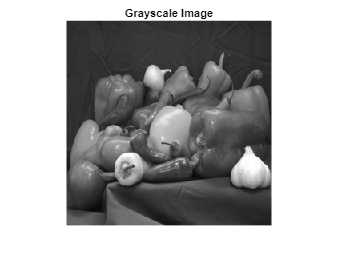

grayImg = rgb2gray(resizedImg);
figure; imshow(grayImg); title('Grayscale Image');

## Example 4: Gaussian Blur

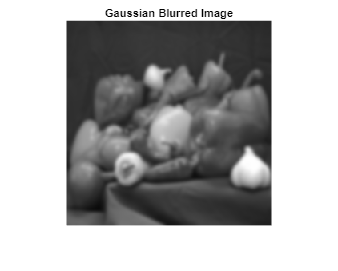

blurredImg = imgaussfilt(grayImg, 2);
figure; imshow(blurredImg); title('Gaussian Blurred Image');

## Example 5: Sharpening

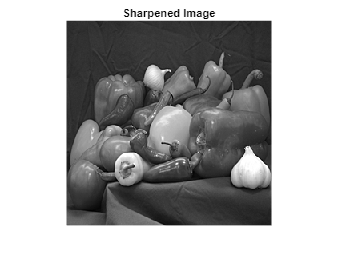

sharpenedImg = imsharpen(grayImg);
figure; imshow(sharpenedImg); title('Sharpened Image');

## Example 6: Histogram Equalization

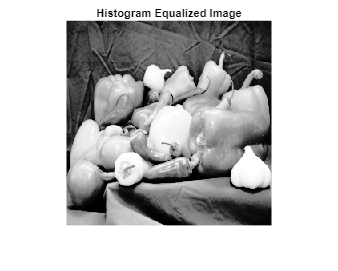

equalizedImg = histeq(grayImg);
figure; imshow(equalizedImg); title('Histogram Equalized Image');

## Example 7: Adaptive Thresholding and Region Detection

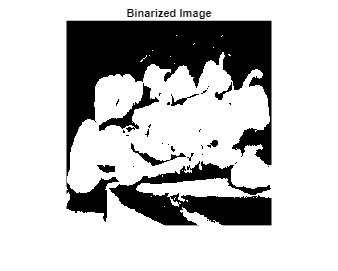

binaryImg = imbinarize(equalizedImg); 
figure; imshow(binaryImg); title('Binarized Image');

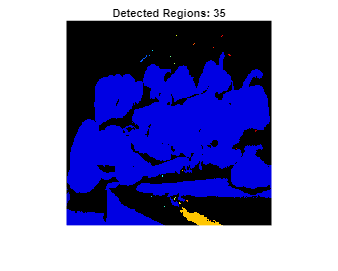

[labeledImg, num] = bwlabel(binaryImg); 
coloredLabels = label2rgb(labeledImg,'jet','k'); 
figure; imshow(coloredLabels); title(['Detected Regions: ', num2str(num)]);

## Save All Outputs

imwrite(resizedImg, 'resized_image.png');
imwrite(grayImg, 'gray_image.png');
imwrite(blurredImg, 'blurred_image.png');
imwrite(sharpenedImg, 'sharpened_image.png');
imwrite(equalizedImg, 'equalized_image.png');